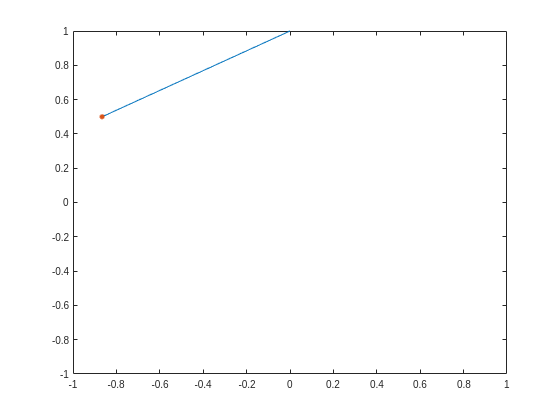

figure

t = 0:0.01:1;
l = 1;
g = 9.8;
theata0 = deg2rad(60);

video = VideoWriter('pendulum');
open(video);

for i = 1:length(t)
    theata = theata0 * cos(sqrt(g/l) * t(i));
    x = l * sin(theata);
    y = l * (1 - cos(theata));

    
    plot([0, x], [1, y], MarkerSize=12)
    hold on
    plot((x), (y), ".", MarkerSize=15)
    axis([-1,1,-1,1])

    frame = getframe;
    writeVideo(video, frame);
    %drawnow 


    hold off
end

close(video);

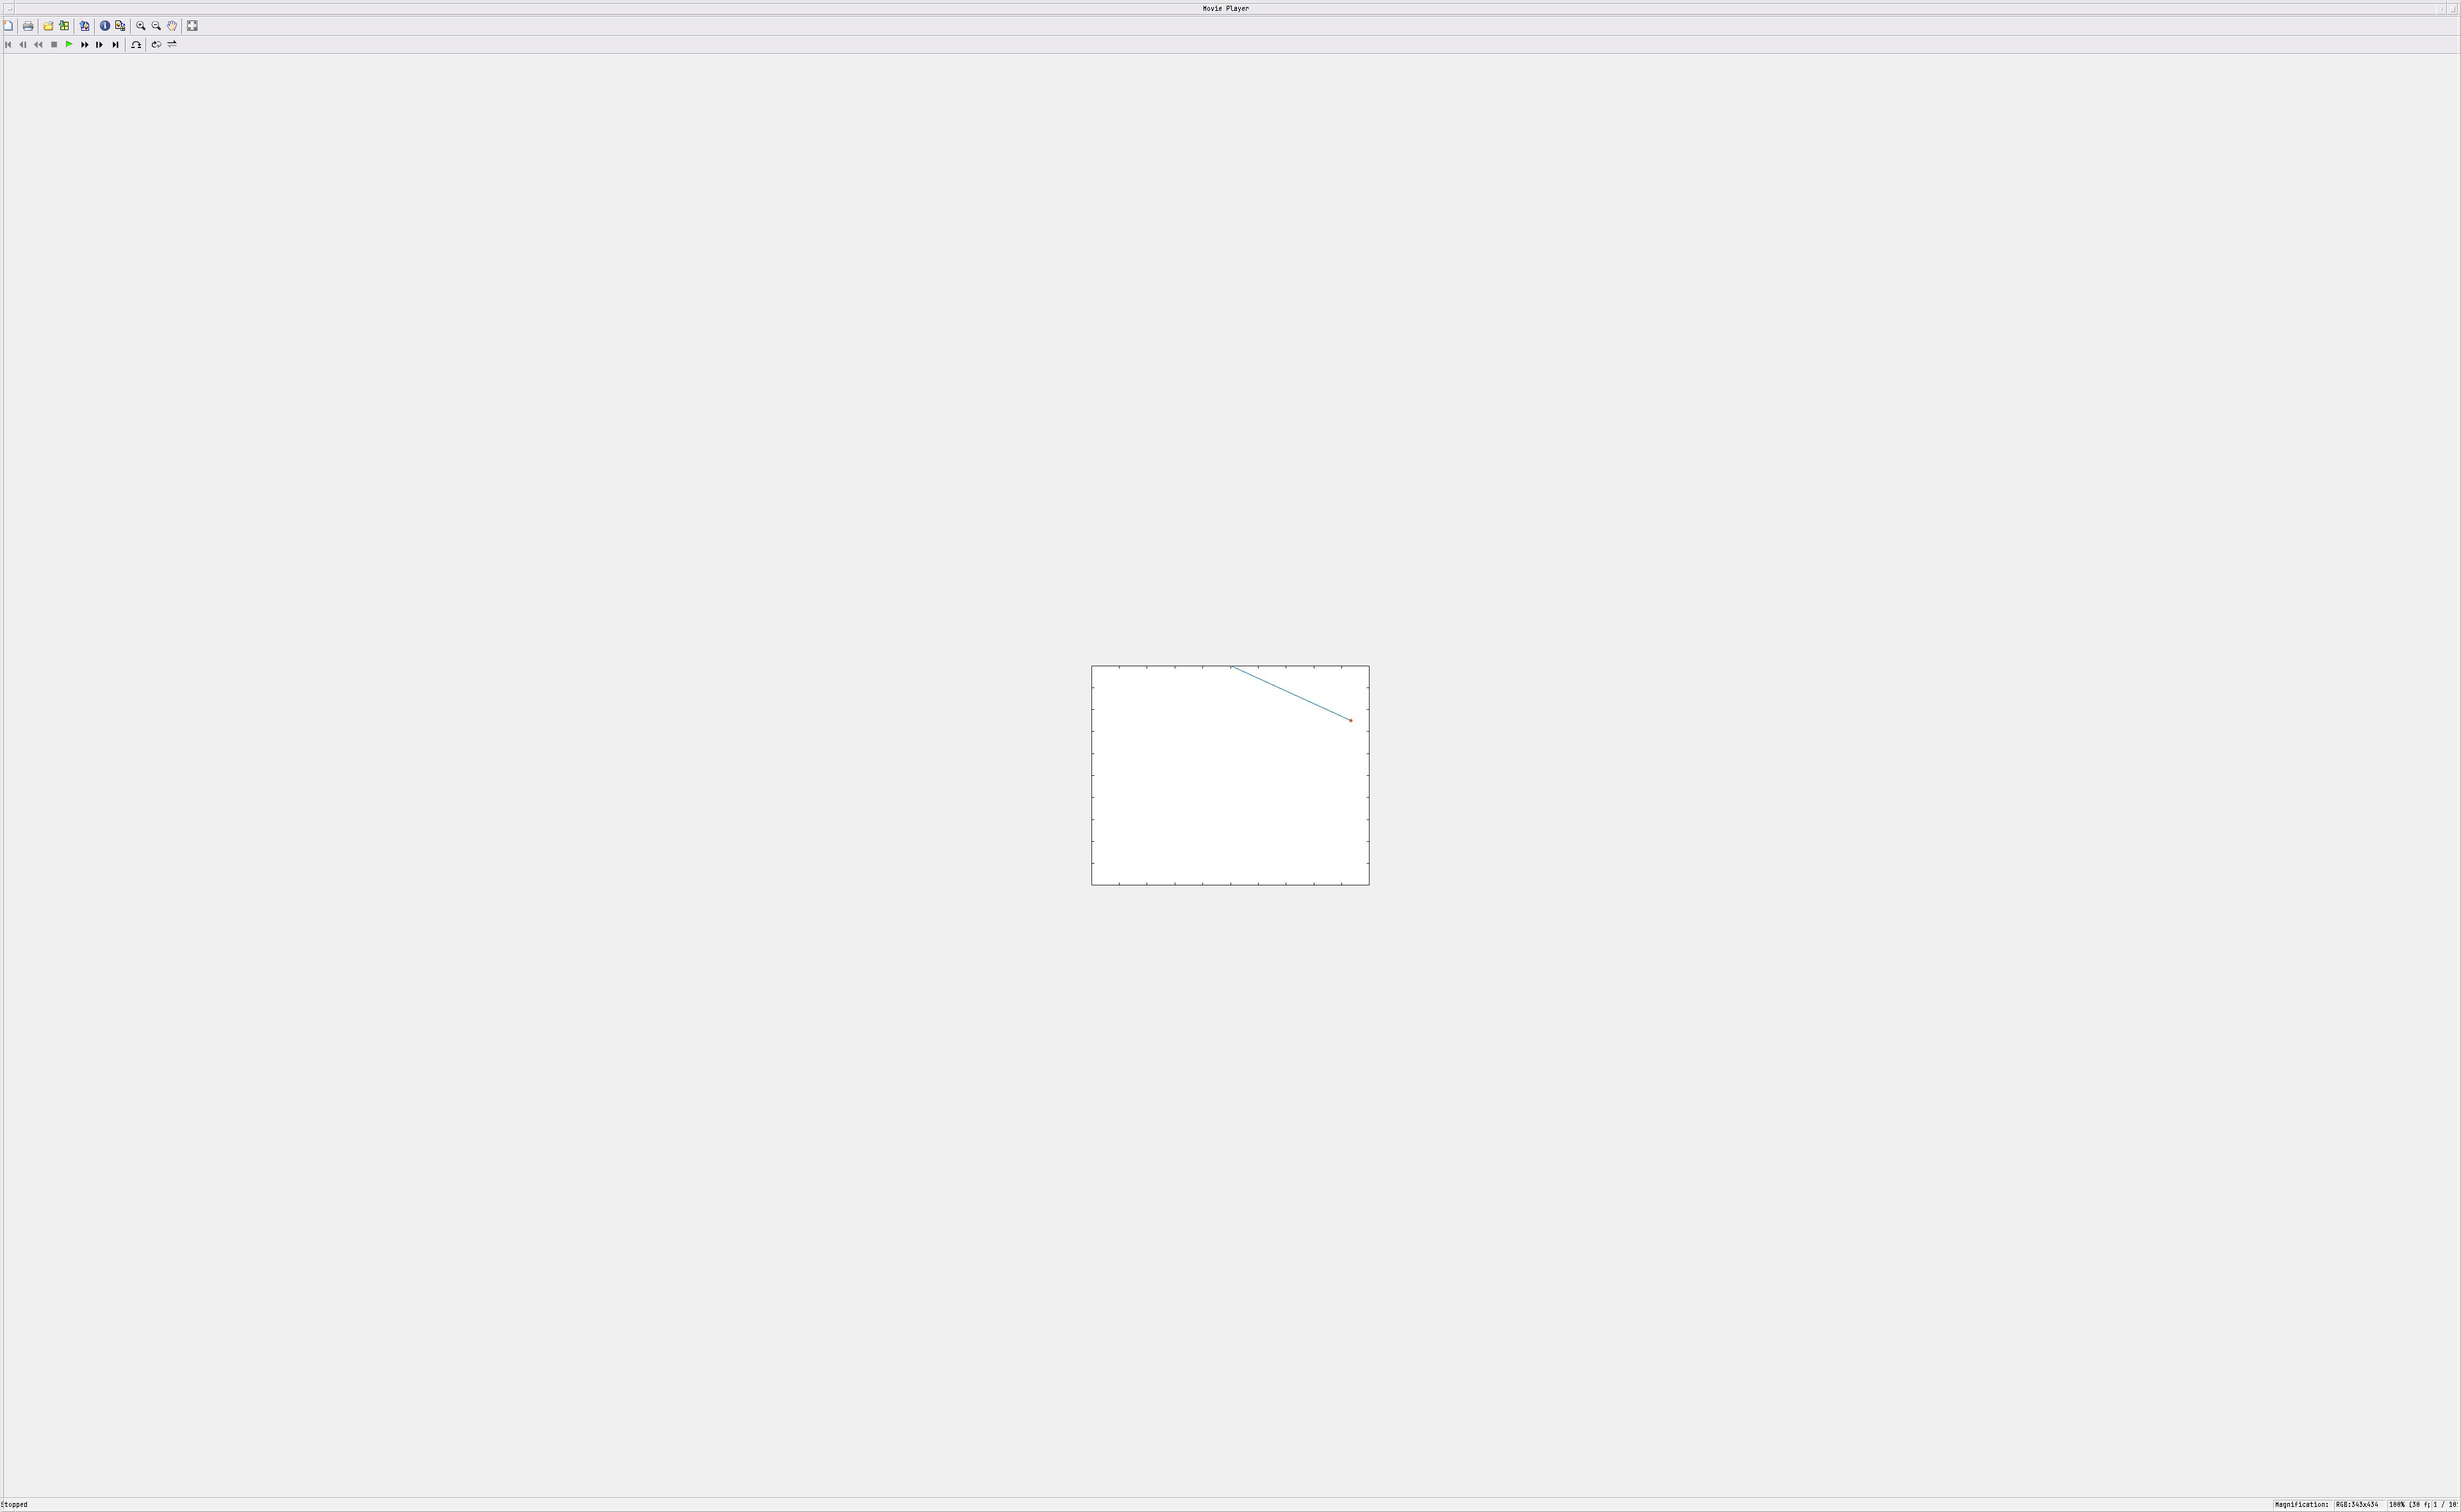

implay pendulum.avi